# Figure 1H

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A038_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 15×5 cell array
    {'siEmi1 TAK'         }    {[2 3]}    {[  2 3]}    {[1]}    {[0]}
    {'siEmi1 CDK2i'       }    {[2 3]}    {[  4 5]}    {[1]}    {[0]}
    {'siEmi1 CDK2i+TAK'   }    {[2 3]}    {[  6 7]}    {[1]}    {[0]}
    {'siEmi1 CDK4/6i'     }    {[2 3]}    {[  8 9]}    {[1]}    {[0]}
    {'siEmi1 Control'     }    {[2 3]}    {[10 11]}    {[1]}    {[0]}
    {'siRif1 TAK'         }    {[4 5]}    {[  2 3]}    {[1]}    {[0]}
    {'siRif1 CDK2i'       }    {[4 5]}    {[  4 5]}    {[1]}    {[0]}
    {'siRif1 CDK2i+TAK'   }    {[4 5]}    {[  6 7]}    {[1]}    {[0]}
    {'siRif1 CDK4/6i'     }    {[4 5]}    {[  8 9]}    {[1]}    {[0]}
    {'siRif1 Control'     }    {[4 5]}    {[10 11]}    {[1]}    {[0]}
    {'siControl TAK'      }    {[6 7]}    {[  2 3]}    {[1]}    {[0]}
    {'siControl CDK2i'    }    {[6 7]}    {[  4 5]}    {[1]}    {[0]}
    {'siControl CDK2i+TAK'}    {[6 7]}    {[  6 7]}    {[1]}    {[0]}
    {'siControl CDK4/6i'  }    {[6 7]}    {[  8 9]}    {[1]} 


framesPerHr = 60/12;

timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
   
end

1 Cell trace

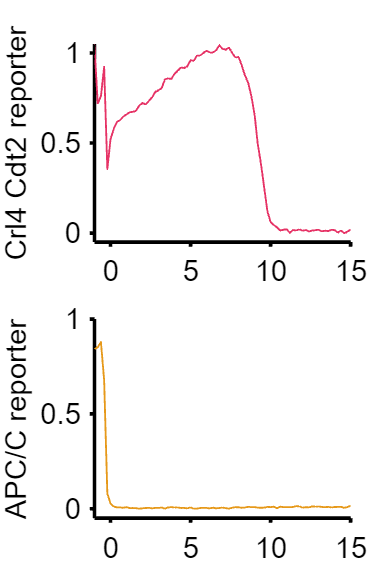


figure ('units','inches','position',[0 0 4 6])

conds = [5];
for i=1:length(conds)

    inds = true(size(S(conds(i)).apcNormM(:,1))) & S(conds(i)).POI_realtime(:,6)>20  & S(conds(i)).POI_realtime(:,1)>2 ;

    cells = find(inds);
    nums =135; %randomly selected representative cell

    timeAligned = xTime-S(conds(i)).POI(nums,1)/framesPerHr;

     subplot(2,1,1), plot(timeAligned,(S(conds(i)).crlNormAct(nums,:))','Color',[.9 .2 .4],'LineWidth',1)
    
   
    ylabel('Crl4 Cdt2 reporter')
    ylim([-.05 1.05])
       xlim([-1 15])
       xticks(0:5:20)
      
         set(gca,'box','off')



    subplot(2,1,2), plot(timeAligned,S(conds(i)).apcNorm(nums,:)','Color',[.9 .6 .1],'LineWidth',1)
   
    ylabel('APC/C reporter')
    ylim([-.05 1])
    xlim([-1 15])
      xticks(0:5:20)
  
    
       set(gca,'box','off')
   
end



% print_pdf('fig_1H.pdf')